## 2. Data Modality: Local Field Potentials

### 2.1. Phase-Locking Value (PLV) Analysis

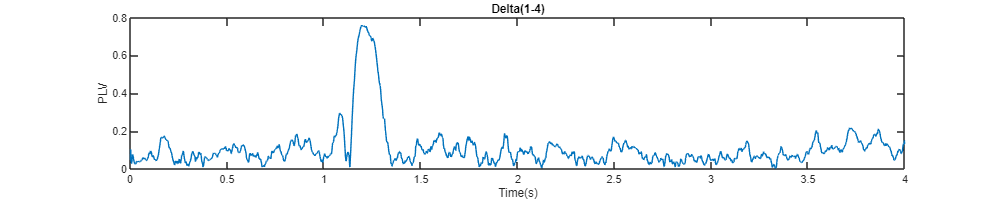

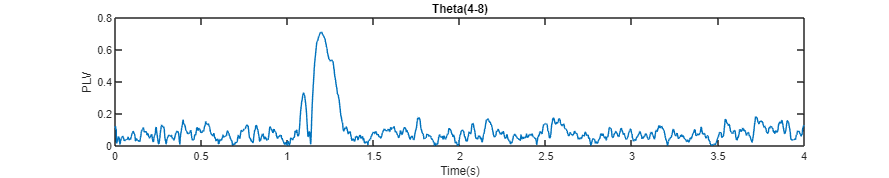

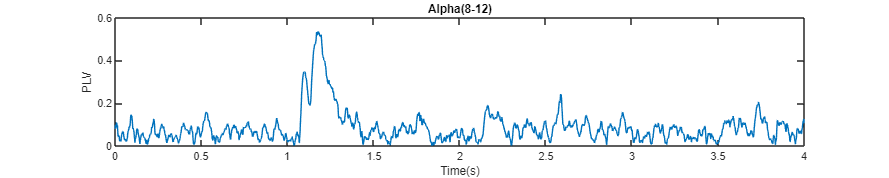

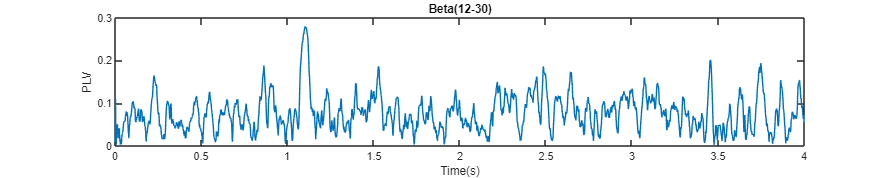

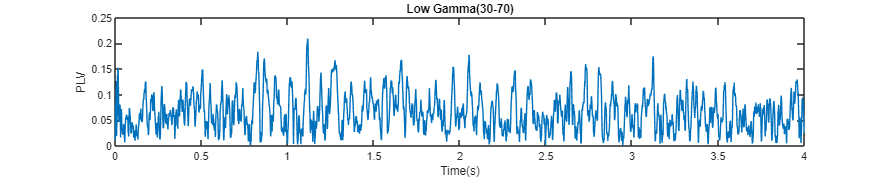

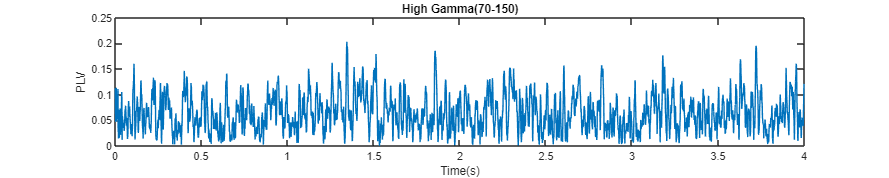

for i = 1:6
    range = [[1 4];[4 8];[8 12];[12 30];[30 70];[70 150]];
    titles = ["Delta(1-4)","Theta(4-8)","Alpha(8-12)","Beta(12-30)","Low Gamma(30-70)","High Gamma(70-150)"];
    plv = PLV(X_in_sessions,1000,100,range(i,:));
    f = figure;
    f.Position = [10 10 1000 200];
    plot((0:size(X_in_sessions, 2)-1)/1000, plv);
    xlabel('Time(s)'); 
    title(titles(i));
    ylabel('PLV');
end

for i = 1:6
    range = [[1 4];[4 8];[8 12];[12 30];[30 70];[70 150]];
    titles = ["Delta(1-4): ","Theta(4-8): ","Alpha(8-12): ","Beta(12-30): ","Low Gamma(30-70): ","High Gamma(70-150): "];
    plv = PLV(X_in_sessions,1000,100,range(i,:));
    plv_mean = mean(plv(1200:1225,:));
    p_value = permutation(X_in_sessions,1000,100,range(i,:),plv_mean);
    if(i==1)
        disp("p_values in permutation test:");
    end
    disp(strcat(titles(i),num2str(p_value)));
end

p_values in permutation test:


Delta(1-4): 0
Theta(4-8): 0
Alpha(8-12): 0
Beta(12-30): 0.28
Low Gamma(30-70): 0.84
High Gamma(70-150): 0.96


### 2.2. Linear Granger Causality (LGC) Analysis 

b.

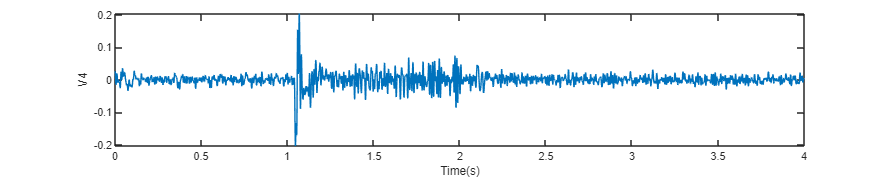

V4_signal = mean(X_in_sessions(1,:,:),3);
FEF_signal = mean(X_in_sessions(2,:,:),3);
plot((0:size(X_in_sessions, 2)-1)/1000, V4_signal);
xlabel('Time(s)'); 
ylabel('V4');

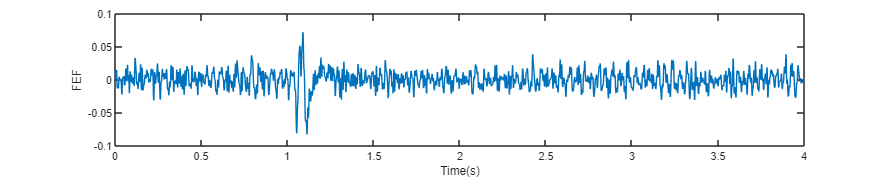

plot((0:size(X_in_sessions, 2)-1)/1000, FEF_signal);
xlabel('Time(s)'); 
ylabel('FEF');

[h,pValue,stat,cValue] = adftest(V4_signal)

h = logical
   1


pValue = 1.0000e-03

stat = -13.7825

cValue = -1.9416

[h,pValue,stat,cValue] = adftest(FEF_signal)

h = logical
   1


pValue = 1.0000e-03

stat = -10.7140

cValue = -1.9416

c.

srate = 1000;
range = 0.5;
wo = 2/srate*range;
filtPts = fir1(100,wo);
filteredData = filter(filtPts, 1, X_in_sessions, [], 2);
[b,a] = iirnotch(wo,wo/35);
filteredData = filter(b,a,filteredData, [], 2);
normalizedData = normalize(filteredData,3);
diffData = diff(normalizedData);

d.

time_lim = size(X_in_sessions,2);
step = 150;
arr_size = ((time_lim-step)/10);
V4toFEF = zeros(arr_size,1);
FEFtoV4 = zeros(arr_size,1);
pval_V4toFEF = zeros(arr_size,1);
pval_FEFtoV4 = zeros(arr_size,1);
time = zeros(arr_size,1);
i = 1;
for t = 1:10:time_lim-step
    if(t+step>time_lim)
        w_end = time_lim;
    else
        w_end = t+step;
    end 
    [F,sig,pval] = GCCA(X_in_sessions(:,t:w_end,:));
    V4toFEF(i,1) = F(1,2);
    FEFtoV4(i,1) = F(2,1);
    pval_V4toFEF(i,1) = pval(1,2);
    pval_FEFtoV4(i,1) = pval(2,1);
    time(i,1) = t/1000;
    i= i+1;
end

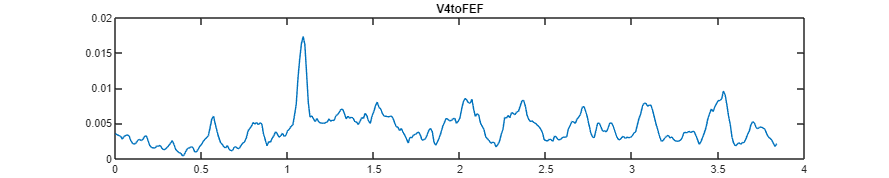

f = figure;
f.Position = [10 10 1000 200];
plot(time,V4toFEF);
title('V4toFEF');

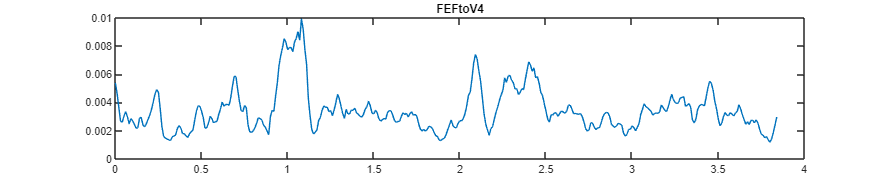

plot(time,FEFtoV4);
title('FEFtoV4');

function p_value = permutation(eeg_data,srate,order,range,mean_plv)
    mean_values = zeros(50,1);
    for r = 1:50
        null_data = generate_null_data(eeg_data);
        plv = PLV(null_data, srate,order,range);
        mean_plv_null = mean(plv(1200:1225,:));
        mean_values(r,1) = mean_plv_null;
    end
    p_value = (sum(mean_values>=abs(mean_plv))+sum(mean_values<=-1*abs(mean_plv)))/50;
end

function null_data = generate_null_data2(eeg_data)
    time = size(eeg_data,2);
    trial = size(eeg_data,3);
    null_data = zeros(size(eeg_data,1),size(eeg_data,2),size(eeg_data,3));
    for t = 1:time
        data1 = squeeze(eeg_data(1,t,:));
        data2 = squeeze(eeg_data(2,t,:));
        combined = [data1; data2];
        combined = combined(randperm(length(combined)));
        null_data(1,t,:) = combined(1:trial,:);
        null_data(2,t,:) = combined(trial+1:trial*2,:);
    end
end

function null_data = generate_null_data(eeg_data)
    null_data = zeros(size(eeg_data,1)*size(eeg_data,2)*size(eeg_data,3),1);
    null_data(:,1) = eeg_data(:);
    null_data = null_data(randperm(length(null_data)));
    null_data = reshape(null_data,size(eeg_data,1),size(eeg_data,2),size(eeg_data,3));
end

function plv = PLV(eegData, srate,order,range)
    numChannels = size(eegData, 1);
    numTrials = size(eegData, 3);
    filtPts = fir1(order, 2/srate*range);
    filteredData = filter(filtPts, 1, eegData, [], 2);
    for channelCount = 1:numChannels
        filteredData(channelCount, :, :) = angle(hilbert(squeeze(filteredData(channelCount, :, :))));
    end
    plv = zeros(size(filteredData, 2), 1);
    channelData1 = squeeze(filteredData(1, :, :));
    ChannelData2 = squeeze(filteredData(2, :, :));
    plv(:,1) = abs(sum(exp(1i*(channelData1(:,:) - ChannelData2(:,:))), 2))/numTrials;
    %plv = normalize(plv);
end

function [F,sig,pval] = GCCA(X)
    ntrials   = size(X, 3);     % number of trials
    nobs      = size(X, 2);     % number of observations per trial
    nvars     = size(X, 1);     % number of nodes

    regmode   = 'OLS';  % VAR model estimation regression mode ('OLS', 'LWR' or empty for default)
    %icregmode = 'LWR';  % information criteria regression mode ('OLS', 'LWR' or empty for default)

    morder    = 20;  % model order to use ('actual', 'AIC', 'BIC' or supplied numerical value)
    %momax     = 20;     % maximum model order for model order estimation
    tstat     = 'F';     % statistical test for MVGC:  'chi2' for Geweke's chi2 test (default) or'F' for Granger's F-test
    alpha     = 0.05;   % significance level for significance test
    mhtc      = 'FDR';  % multiple hypothesis test correction (see routine 'significance')


    [F,A,SIG] = GCCA_tsdata_to_pwcgc(X,morder,regmode); % use same model order for reduced as for full regressions
    pval = mvgc_pval(F,morder,nobs,ntrials,1,1,nvars-2,tstat);
    sig  = significance(pval,alpha,mhtc);
end